# Image Processing Operator Approximation Using Deep Learning

This example shows how to approximate an image filtering operation using a multiscale context aggregation network (CAN).

The example shows how to train a multiscale CAN network to approximate a bilateral filter, and also provides a pretrained network. If you choose to train the network, use of a CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended. Use of a GPU requires the Parallel Computing Toolbox™.

## Introduction

Operator approximation finds alternative ways to process images such that the result resembles the output from a conventional image processing operation or pipeline. The goal of operator approximation is often to reduce the time required to process an image.

Several classical and deep learning techniques have been proposed to perform operator approximation. Some classical techniques improve the efficiency of a single algorithm but cannot be generalized to other operations. Another common technique approximates a wide range of operations by applying the operator to a low resolution copy of an image, but the loss of high-frequency content limits the accuracy of the approximation.

Deep learning solutions enable the approximation of more general and complex operations. For example, the multiscale context aggregation network (CAN) presented by Q. Chen [1] can approximate multiscale tone mapping, photographic style transfer, nonlocal dehazing, and pencil drawing. Multiscale CAN trains on full-resolution images for greater accuracy in processing high-frequency details. After the network is trained, the network can bypass the conventional processing operation and process images directly.

This example explores how to train a multiscale CAN to approximate a bilateral image filtering operation, which reduces image noise while preserving edge sharpness. The example presents the complete training and inference workflow, which includes the process of creating a training datastore, selecting training options, training the network, and using the network to process test images.

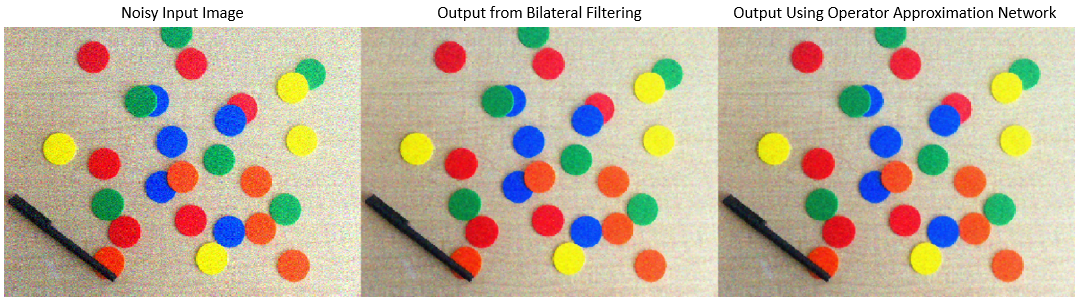

## The Operator Approximation Network

The multiscale CAN is trained to minimize the $l_2$ loss between the conventional output of an image processing operation and the network response after processing the input image using multiscale context aggregation. Multiscale context aggregation looks for information about each pixel from across the entire image, rather than limiting the search to a small neighborhood surrounding the pixel.

    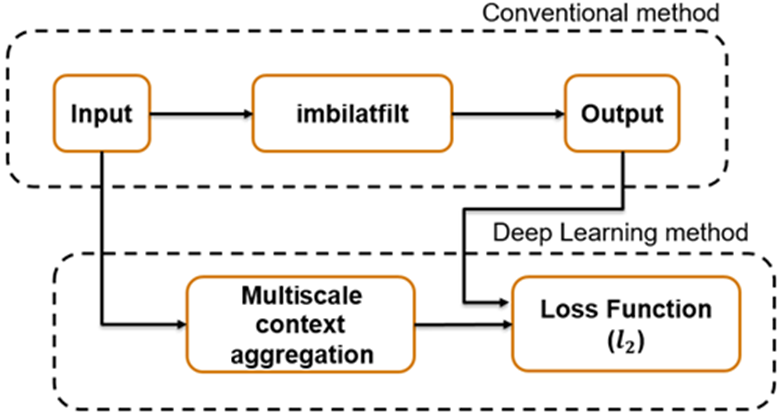

To help the network learn global image properties, the multiscale CAN architecture has a large receptive field. The first and last layers have the same size because the operator should not change the size of the image. Successive intermediate layers are dilated by exponentially increasing scale factors (hence the "multiscale" nature of the CAN). Dilation enables the network to look for spatially separated features at various spatial frequencies, without reducing the resolution of the image. After each convolution layer, the network uses adaptive normalization to balance the impact of batch normalization and the identity mapping on the approximated operator.

## Download Training and Test Data

Download the IAPR TC-12 Benchmark, which consists of 20,000 still natural images [2]. The data set includes photos of people, animals, cities, and more. The size of the data file is ~1.8 GB. If you do not want to download the training data set needed to train the network, then you can load the pretrained CAN by typing `load('trainedOperatorLearning-Epoch-181.mat');` at the command line. Then, go directly to the Perform Bilateral Filtering Approximation Using Multiscale CAN section in this example.

imagesDir = tempdir;
url_1 = 'http://www-i6.informatik.rwth-aachen.de/imageclef/resources/iaprtc12.tgz';
downloadIAPRTC12Data(url_1,imagesDir);

This example trains the network with small subset of the IAPRTC-12 Benchmark data.

trainImagesDir = fullfile(imagesDir,'iaprtc12','images','39');
exts = {'.jpg','.bmp','.png'};
pristineImages = imageDatastore(trainImagesDir,'FileExtensions',exts);

List the number of training images.

numel(pristineImages.Files)

## Prepare Training Data

To create a training data set, read in pristine images and write out images that have been bilateral filtered. The filtered images are stored on disk in the directory specified by `preprocessDataDir`.

preprocessDataDir = [trainImagesDir filesep 'preprocessedDataset'];

Use the helper function `bilateralFilterDataset` to preprocess the training data. This function is attached to the example as a supporting file.

The helper function performs these operations for each pristine image in `inputImages`:

- Calculate the degree of smoothing for bilateral filtering. Smoothing the filtered image reduces image noise.

- Perform bilateral filtering using [`imbilatfilt`](docid:images_ref#mw_d338440a-4133-482f-8032-180c7b0cda17).

- Save the filtered image to disk using [`imwrite`](docid:matlab_ref#btv3cny-1).

bilateralFilterDataset(pristineImages,preprocessDataDir);

## Define Random Patch Extraction Datastore for Training

Use a random patch extraction datastore to feed the training data to the network. This datastore extracts random corresponding patches from two image datastores that contain the network inputs and desired network responses.

In this example, the network inputs are the pristine images in `pristineImages`. The desired network responses are the processed images after bilateral filtering. Create an image datastore called `bilatFilteredImages` from the collection of bilateral filtered image files.

bilatFilteredImages = imageDatastore(preprocessDataDir,'FileExtensions',exts);

Create a [`randomPatchExtractionDatastore`](docid:images_ref#mw_19a16ac8-a068-411c-8f32-def517a4399a) from the two image datastores. Specify a patch size of 256-by-256 pixels. Specify '`PatchesPerImage`' to extract one randomly-positioned patch from each pair of images during training. Specify a mini-batch size of one.

miniBatchSize = 1;
patchSize = [256 256];
dsTrain = randomPatchExtractionDatastore(pristineImages,bilatFilteredImages,patchSize, ....
    'PatchesPerImage',1);
dsTrain.MiniBatchSize = miniBatchSize;

The `randomPatchExtractionDatastore` provides mini-batches of data to the network at each iteration of the epoch. Perform a read operation on the datastore to explore the data.

inputBatch = read(dsTrain);
disp(inputBatch)

## Set Up Multiscale CAN Layers

This example defines the multiscale CAN using layers from Deep Learning Toolbox™, including:

- [`imageInputLayer`](docid:nnet_ref#mw_fcd2d9b1-ce25-49d1-9d06-b7cf41594ff4) - Image input layer

- [`convolution2dLayer`](docid:nnet_ref#mw_2d97b6cd-f8aa-4fad-88d6-d34875484820) - 2D convolution layer for convolutional neural networks

- [`batchNormalizationLayer`](docid:nnet_ref#mw_b7913af4-3a40-4020-bb2c-18c946f5eadd) - Batch normalization layer

- [`leakyReluLayer`](docid:nnet_ref#mw_dd5ec989-4dec-4016-96ce-3a1b444e1154) - Leaky rectified linear unit layer

- [`regressionLayer`](docid:nnet_ref#bvlk3f6) - Regression output layer for a neural network

Two custom scale layers are added to implement an adaptive batch normalization layer. These layers are attached as supporting files to this example.

- **adaptiveNormalizationMu **- Scale layer that adjusts the strengths of the batch-normalization branch

- **adaptiveNormalizationLambda **- Scale layer that adjusts the strengths of the identity branch

The first layer, `imageInputLayer`, operates on image patches. The patch size is based on the network receptive field, which is the spatial image region that affects the response of top-most layer in the network. Ideally, the network receptive field is the same as the image size so that it can see all the high level features in the image. For a bilateral filter, the approximation image patch size is fixed to 256-by-256.

networkDepth = 10;
numberOfFilters = 32;
firstLayer = imageInputLayer([256 256 3],'Name','InputLayer','Normalization','none');

The image input layer is followed by a 2-D convolution layer that contains 32 filters of size 3-by-3. Zero-pad the inputs to each convolution layer so that feature maps remain the same size as the input after each convolution. Initialize the weights to the identity matrix.

Wgts = zeros(3,3,3,numberOfFilters); 
for ii = 1:3
    Wgts(2,2,ii,ii) = 1;
end
convolutionLayer = convolution2dLayer(3,numberOfFilters,'Padding',1, ...
    'Weights',Wgts,'Name','Conv1');

Each convolution layer is followed by a batch normalization layer and an adaptive normalization scale layer that adjusts the strengths of the batch-normalization branch. Later, this example will create the corresponding adaptive normalization scale layer that adjusts the strength of the identity branch. For now, follow the `adaptiveNormalizationMu` layer with an addition layer. Finally, specify a leaky ReLU layer with a scalar multiplier of `0.2` for negative inputs.

batchNorm = batchNormalizationLayer('Name','BN1');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu1');
addLayer = additionLayer(2,'Name','add1');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky1');

Specify the middle layers of the network following the same pattern. Successive convolution layers have a dilation factor that scales exponentially with the network depth.

middleLayers = [convolutionLayer batchNorm adaptiveMu addLayer leakyrelLayer];
    
Wgts = zeros(3,3,numberOfFilters,numberOfFilters);
for ii = 1:numberOfFilters
    Wgts(2,2,ii,ii) = 1;
end
    
for layerNumber = 2:networkDepth-2
    dilationFactor = 2^(layerNumber-1);
    padding = dilationFactor;
    conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
        'Padding',padding,'DilationFactor',dilationFactor, ...
        'Weights',Wgts,'Name',['Conv' num2str(layerNumber)]);
    batchNorm = batchNormalizationLayer('Name',['BN' num2str(layerNumber)]);
    adaptiveMu = adaptiveNormalizationMu(numberOfFilters,['Mu' num2str(layerNumber)]);
    addLayer = additionLayer(2,'Name',['add' num2str(layerNumber)]);
    leakyrelLayer = leakyReluLayer(0.2, 'Name', ['Leaky' num2str(layerNumber)]);
    middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];    
end

Do not apply a dilation factor to the second-to-last convolution layer.

conv2dLayer = convolution2dLayer(3,numberOfFilters, ...
    'Padding',1,'Weights',Wgts,'Name','Conv9');

batchNorm = batchNormalizationLayer('Name','AN9');
adaptiveMu = adaptiveNormalizationMu(numberOfFilters,'Mu9');
addLayer = additionLayer(2,'Name','add9');
leakyrelLayer = leakyReluLayer(0.2,'Name','Leaky9');
middleLayers = [middleLayers conv2dLayer batchNorm adaptiveMu addLayer leakyrelLayer];

The last convolution layer has a single filter of size 1-by-1-by-32-by-3 that reconstructs the image.

Wgts = sqrt(2/(9*numberOfFilters))*randn(1,1,numberOfFilters,3);
conv2dLayer = convolution2dLayer(1,3,'NumChannels',numberOfFilters, ...
    'Weights',Wgts,'Name','Conv10');

The last layer is a regression layer instead of a leaky ReLU layer. The regression layer computes the mean-squared error between the bilateral-filtered image and the network prediction.

finalLayers = [conv2dLayer 
    regressionLayer('Name','FinalRegressionLayer')
];

Concatenate all the layers.

layers = [firstLayer middleLayers finalLayers'];
lgraph = layerGraph(layers);

Create skip connections, which act as the identity branch for the adaptive normalization equation. Connect the skip connections to the addition layers.

skipConv1 = adaptiveNormalizationLambda(numberOfFilters,'Lambda1');
skipConv2 = adaptiveNormalizationLambda(numberOfFilters,'Lambda2');
skipConv3 = adaptiveNormalizationLambda(numberOfFilters,'Lambda3');
skipConv4 = adaptiveNormalizationLambda(numberOfFilters,'Lambda4');
skipConv5 = adaptiveNormalizationLambda(numberOfFilters,'Lambda5');
skipConv6 = adaptiveNormalizationLambda(numberOfFilters,'Lambda6');
skipConv7 = adaptiveNormalizationLambda(numberOfFilters,'Lambda7');
skipConv8 = adaptiveNormalizationLambda(numberOfFilters,'Lambda8');
skipConv9 = adaptiveNormalizationLambda(numberOfFilters,'Lambda9');

lgraph = addLayers(lgraph,skipConv1);
lgraph = connectLayers(lgraph,'Conv1','Lambda1');
lgraph = connectLayers(lgraph,'Lambda1','add1/in2');

lgraph = addLayers(lgraph,skipConv2);
lgraph = connectLayers(lgraph,'Conv2','Lambda2');
lgraph = connectLayers(lgraph,'Lambda2','add2/in2');

lgraph = addLayers(lgraph,skipConv3);
lgraph = connectLayers(lgraph,'Conv3','Lambda3');
lgraph = connectLayers(lgraph,'Lambda3','add3/in2');

lgraph = addLayers(lgraph,skipConv4);
lgraph = connectLayers(lgraph,'Conv4','Lambda4');
lgraph = connectLayers(lgraph,'Lambda4','add4/in2');

lgraph = addLayers(lgraph,skipConv5);
lgraph = connectLayers(lgraph,'Conv5','Lambda5');
lgraph = connectLayers(lgraph,'Lambda5','add5/in2');

lgraph = addLayers(lgraph,skipConv6);
lgraph = connectLayers(lgraph,'Conv6','Lambda6');
lgraph = connectLayers(lgraph,'Lambda6','add6/in2');

lgraph = addLayers(lgraph,skipConv7);
lgraph = connectLayers(lgraph,'Conv7','Lambda7');
lgraph = connectLayers(lgraph,'Lambda7','add7/in2');

lgraph = addLayers(lgraph,skipConv8);
lgraph = connectLayers(lgraph,'Conv8','Lambda8');
lgraph = connectLayers(lgraph,'Lambda8','add8/in2');

lgraph = addLayers(lgraph,skipConv9);
lgraph = connectLayers(lgraph,'Conv9','Lambda9');
lgraph = connectLayers(lgraph,'Lambda9','add9/in2');

Plot the layer graph.

plot(lgraph)

## Specify Training Options

Train the network using the Adam optimizer. Specify the hyperparameter settings by using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function. Use the default values of `0.9` for '`Momentum`' and `0.0001` for '`L2Regularization`' (weight decay). Specify a constant learning rate of `0.0001`. Train for 181 epochs.

maxEpochs = 181;
initLearningRate = 0.0001;
miniBatchSize = 1;

options = trainingOptions('adam', ...
    'InitialLearnRate',initLearningRate, ...
    'MaxEpochs',maxEpochs, ...
    'MiniBatchSize',miniBatchSize, ...
    'Plots','training-progress', ...
    'Verbose',false);

## Train the Network

Now that the data source and training options are configured, train the multiscale CAN using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) `function`. To train the network, set the `doTraining` parameter in the following code to `true`. A CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended for training.

If you keep the `doTraining` parameter in the following code as `false`, then the example returns a pretrained multiscale CAN that has been trained to approximate a bilateral filter.

*Note: Training usually takes about 15 hours on an *`NVIDIA™ Titan X`* and can take even longer depending on your GPU hardware.*

doTraining = false;
if doTraining
    modelDateTime = datestr(now,'dd-mmm-yyyy-HH-MM-SS');
    net = trainNetwork(dsTrain,lgraph,options);
    save(['trainedOperatorLearning-' modelDateTime '-Epoch-' num2str(maxEpochs) '.mat'],'net');
else
    load('trainedOperatorLearning-Epoch-181.mat');
end

## Perform Bilateral Filtering Approximation Using Multiscale CAN

To process an image using a trained multiscale CAN network that approximates a bilateral filter, follow the remaining steps of this example. The remainder of the example shows how to:

- Create a sample noisy input image from a reference image.

- Perform conventional bilateral filtering of the noisy image using the [`imbilatfilt`](docid:images_ref#mw_d338440a-4133-482f-8032-180c7b0cda17) function.

- Perform an approximation to bilateral filtering on the noisy image using the CAN.

- Visually compare the denoised images from operator approximation and conventional bilateral filtering.

- Evaluate the quality of the denoised images by quantifying the similarity of the images to the pristine reference image.

## Create Sample Noisy Image

Create a sample noisy image that will be used to compare the results of operator approximation to conventional bilateral filtering. The test data set, `testImages`, contains 21 pristine images shipped in Image Processing Toolbox™. Load the images into an `imageDatastore`.

exts = {'.jpg','.png'};
fileNames = {'sherlock.jpg','car2.jpg','fabric.png','greens.jpg','hands1.jpg','kobi.png',...
    'lighthouse.png','micromarket.jpg','office_4.jpg','onion.png','pears.png','yellowlily.jpg',...
    'indiancorn.jpg','flamingos.jpg','sevilla.jpg','llama.jpg','parkavenue.jpg',...
    'peacock.jpg','car1.jpg','strawberries.jpg','wagon.jpg'};
filePath = [fullfile(matlabroot,'toolbox','images','imdata') filesep];
filePathNames = strcat(filePath,fileNames);
testImages = imageDatastore(filePathNames,'FileExtensions',exts);

Display the test images as a montage.

montage(testImages)

Select one of the images to use as the reference image for bilateral filtering. Convert the image to data type `uint8`.

indx = 3; % Index of image to read from the test image datastore
Ireference = readimage(testImages,indx);
Ireference = im2uint8(Ireference);

You can optionally use your own image as the reference image. Note that the size of the test image must be at least 256-by-256. If the test image is smaller than 256-by-256, then increase the image size by using the [`imresize`](docid:images_ref#buxswkh-1) function. The network also requires an RGB test image. If the test image is grayscale, then convert the image to RGB by using the [`cat`](docid:matlab_ref#f70-456588) function to concatenate three copies of the original image along the third dimension.

Display the reference image.

imshow(Ireference)
title('Pristine Reference Image')

Use the [`imnoise`](docid:images_ref#f5-195189) function to add zero-mean Gaussian white noise with a variance of 0.00001 to the reference image.

Inoisy = imnoise(Ireference,'gaussian',0.00001);
imshow(Inoisy)
title('Noisy Image')

## Filter Image Using Bilateral Filtering

Conventional bilateral filtering is a standard way to reduce image noise while preserving edge sharpness. Use the [`imbilatfilt`](docid:images_ref#mw_d338440a-4133-482f-8032-180c7b0cda17) function to apply a bilateral filter to the noisy image. Specify a degree of smoothing equal to the variance of pixel values.

degreeOfSmoothing = var(double(Inoisy(:)));
Ibilat = imbilatfilt(Inoisy,degreeOfSmoothing);
imshow(Ibilat)
title('Denoised Image Obtained Using Bilateral Filtering')

## Process Image Using Trained Network

Pass the normalized input image through the trained network and observe the [`activations`](docid:nnet_ref#mw_70f86305-04b8-41c4-9276-0d1a9bcb9e96) from the final layer (a regression layer). The output of the network is the desired denoised image.

Iapprox = activations(net,Inoisy,'FinalRegressionLayer');

Image Processing Toolbox™ requires floating point images to have pixel values in the range [0, 1]. Use the [`rescale`](docid:matlab_ref#mw_e944b9ed-e3a1-4137-b750-1cbb369a1d6b) function to scale the pixel values to this range, then convert the image to `uint8`.

Iapprox = rescale(Iapprox);
Iapprox = im2uint8(Iapprox);
imshow(Iapprox)
title('Denoised Image Obtained Using Multiscale CAN')

## Visual and Quantitative Comparison

To get a better visual understanding of the denoised images, examine a small region inside each image. Specify a region of interest (ROI) using vector `roi` in the format [*x* *y* *width* *height*]. The elements define the x- and y-coordinate of the top left corner, and the width and height of the ROI.

roi = [300 30 50 50];

Crop the images to this ROI, and display the result as a montage.

montage({imcrop(Ireference,roi),imcrop(Inoisy,roi), ...
    imcrop(Ibilat,roi),imcrop(Iapprox,roi)}, ...
    'Size',[1 4]);
title('Reference Image | Noisy Image | Bilateral-Filtered Image | CAN Prediction');

The CAN removes more noise than conventional bilateral filtering. Both techniques preserve edge sharpness.

Use image quality metrics to quantitatively compare the noisy input image, the bilateral-filtered image, and the operator-approximated image. The reference image is the original reference image, `Ireference`, before adding noise.

Measure the peak signal-to-noise ratio (PSNR) of each image against the reference image. Larger PSNR values generally indicate better image quality. See [`psnr`](docid:images_ref#bt5uhgi-1) for more information about this metric.

noisyPSNR = psnr(Inoisy,Ireference);
bilatPSNR = psnr(Ibilat,Ireference);
approxPSNR = psnr(Iapprox,Ireference);
disp(['PSNR of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyPSNR bilatPSNR approxPSNR])])

Measure the structural similarity index (SSIM) of each image. SSIM assesses the visual impact of three characteristics of an image: luminance, contrast and structure, against a reference image. The closer the SSIM value is to 1, the better the test image agrees with the reference image. See [`ssim`](docid:images_ref#bt5rkbx-1) for more information about this metric.

noisySSIM = ssim(Inoisy,Ireference);
bilatSSIM = ssim(Ibilat,Ireference);
approxSSIM = ssim(Iapprox,Ireference);
disp(['SSIM of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisySSIM bilatSSIM approxSSIM])])

Measure perceptual image quality using the Naturalness Image Quality Evaluator (NIQE). Smaller NIQE scores indicate better perceptual quality. See [`niqe`](docid:images_ref#mw_b03fa30c-0102-4174-9335-bb29e4a663d0) for more information about this metric.

noisyNIQE = niqe(Inoisy);
bilatNIQE = niqe(Ibilat);
approxNIQE = niqe(Iapprox);
disp(['NIQE score of: Noisy Image / Bilateral-Filtered Image / Operator Approximated Image = ', ...
    num2str([noisyNIQE bilatNIQE approxNIQE])])

Compared to conventional bilateral filtering, the operator approximation produces better metric scores.

## References

[1] Chen, Q. J. Xu, and V. Koltun. "Fast Image Processing with Fully-Convolutional Networks." In *Proceedings of the 2017 IEEE Conference on Computer Vision*. Venice, Italy, Oct. 2017, pp. 2516-2525.

[2] Grubinger, M., P. Clough, H. Müller, and T. Deselaers. "The IAPR TC-12 Benchmark: A New Evaluation Resource for Visual Information Systems." *Proceedings of the OntoImage 2006 Language Resources For Content-Based Image Retrieval*. Genoa, Italy. Vol. 5, May 2006, p. 10.

*Copyright 2018 The MathWorks, Inc.*